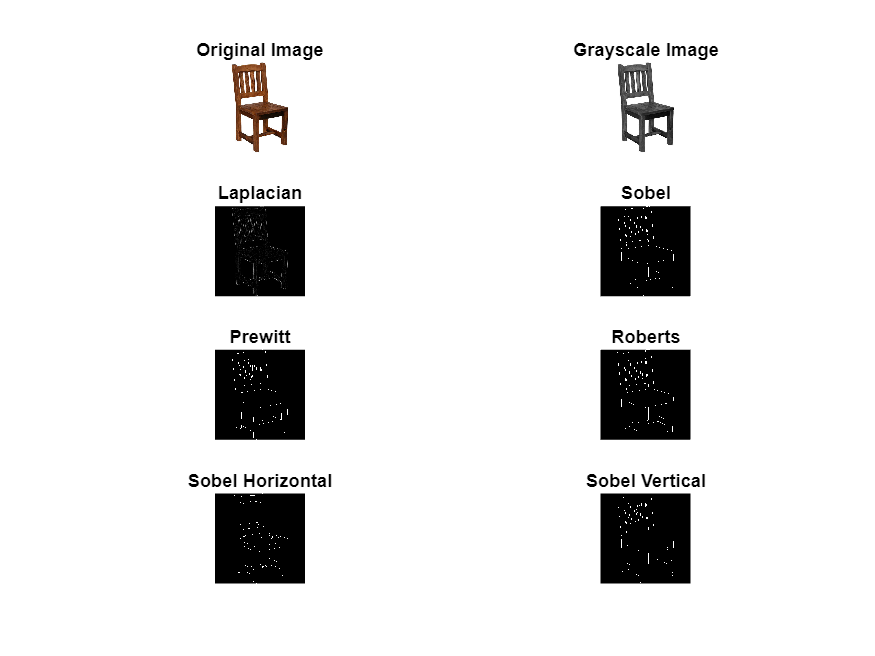

% Implementation of image sharpening filter and edge 
% detection using gradient filter

clc
i=imread('wooden-chair.jpg');

subplot(4,2,1)
imshow(i)
title('Original Image')

subplot(4,2,2)
g=rgb2gray(i);
imshow(g)
title('Grayscale Image')

subplot(4,2,3)
f=fspecial('laplacian',0.05);
im=imfilter(g,f);
imshow(im)
title('Laplacian')

subplot(4,2,4)
s=edge(g,'sobel');
imshow(s)
title('Sobel')

subplot(4,2,5)
p=edge(g,'prewitt');
imshow(p)
title('Prewitt')

subplot(4,2,6)
r=edge(g,'roberts');
imshow(r)
title('Roberts')

[BW,thresh,gv,gh]=edge(g,'sobel',[],'horizontal');
[BW1,thresh1,gv1,gh1]=edge(g,'sobel',[],'vertical');

subplot(4,2,7)
imshow(BW)
title('Sobel Horizontal')

subplot(4,2,8)
imshow(BW1)
title('Sobel Vertical')